clear all; 
close all; 
clc;

% Parameters
step_sizes = [0.01, 0.05, 0.1];  % Step sizes
filter_orders = [32, 64, 128];    % Filter orders

best_SNR = -Inf; % Initialize best SNR
best_mu = 0;
best_M = 0;
SNR_matrix = zeros(length(step_sizes), length(filter_orders));

for i = 1:length(step_sizes)
    for j = 1:length(filter_orders)
        mu = step_sizes(i);
        M = filter_orders(j);

        % Input signal (noise reference)
        x = randn(1000,1);

        % Desired signal (noise to be cancelled)
        d = filter([1 0.5],[1 -0.7],x);

        % Initialize weight vector
        w = zeros(M,1);

        % Buffers
        x_buf = zeros(M,1);
        y_buf = zeros(length(d),1);

        % Main loop
        for n = (M+1):length(x)
            % Shift input buffer
            x_buf = x(n:-1:n-M+1);

            % FIR filter output
            y = w'*x_buf;
            y_buf(n) = y;

            % Error signal
            e = d(n) - y;

            % Update weight vector
            w = w + mu * e * x_buf;
        end

        % Calculate Signal-to-Noise Ratio (SNR)
        SNR_output = snr(d, d - y_buf); % SNR of output signal

        % Store SNR in matrix
        SNR_matrix(i, j) = SNR_output;

        % Determine if current combination is best
        if SNR_output > best_SNR
            best_SNR = SNR_output;
            best_mu = mu;
            best_M = M;
        end
    end
end

% Display best combination
disp(['Best combination - Step size (mu): ' num2str(best_mu) ', Filter order (M): ' num2str(best_M)]);

Best combination - Step size (mu): 0.01, Filter order (M): 32



% Now, use the best_mu and best_M to run the LMS algorithm again

% Parameters
mu = best_mu;
M = best_M;

% Input signal (noise reference)
x = randn(1000,1);

% Desired signal (noise to be cancelled)
d = filter([1 0.5],[1 -0.7],x);

% Initialize weight vector
w = zeros(M,1);

% Buffers
x_buf = zeros(M,1);
y_buf = zeros(length(d),1);

% Main loop
for n = (M+1):length(x)
    % Shift input buffer
    x_buf = x(n:-1:n-M+1);

    % FIR filter output
    y = w'*x_buf;
    y_buf(n) = y;

    % Error signal
    e = d(n) - y;

    % Update weight vector
    w = w + mu * e * x_buf;
end

% Calculate Signal-to-Noise Ratio (SNR)
SNR_input = snr(d, d - x); % SNR of input signal
SNR_output = snr(d, d - y_buf); % SNR of output signal

% Plot results
figure('Position', [100, 100, 800, 800]);

% Plot signals
subplot(4,1,1);
plot(x); hold on; plot(d,'r'); legend('Input','Desired');
ylabel('Amplitude');
title('Input and Desired Signals');

% Plot error signal
subplot(4,1,2);
plot(d-y_buf,'g'); 
ylabel('Amplitude');
title('Error Signal');

% Plot adaptive filter weights
subplot(4,1,3);
plot(w);
ylabel('Weight Value');
xlabel('Tap Index');
title('Adaptive Filter Weights');

% Display SNR
disp(['SNR of input signal: ' num2str(SNR_input) ' dB']);

SNR of input signal: 1.4592 dB


disp(['SNR of output signal: ' num2str(SNR_output) ' dB']);

SNR of output signal: 11.1324 dB


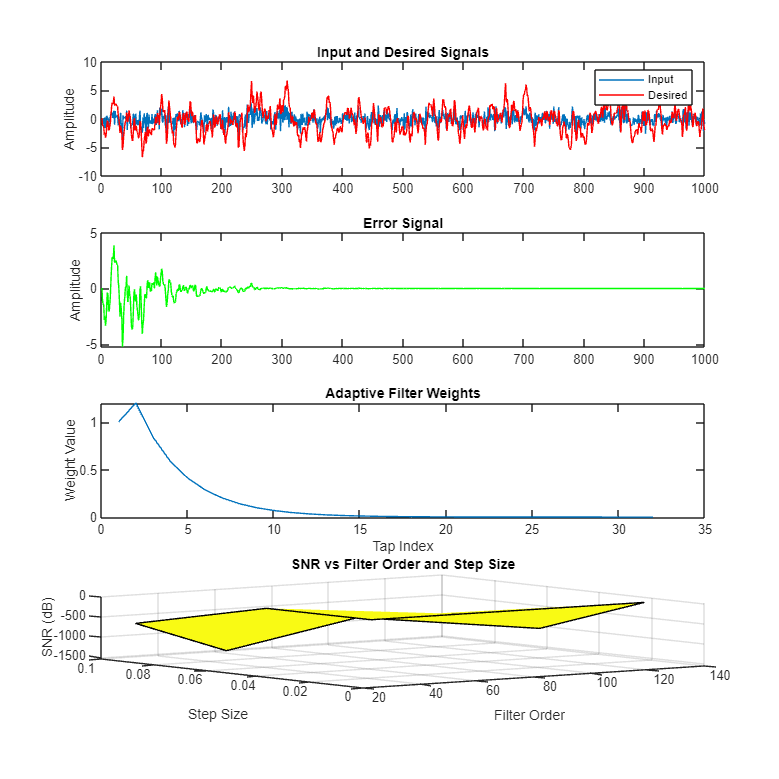


% Plot SNR matrix
subplot(4,1,4);
surf(filter_orders, step_sizes, SNR_matrix);
xlabel('Filter Order');
ylabel('Step Size');
zlabel('SNR (dB)');
title('SNR vs Filter Order and Step Size');